# Confined IRKA-PH (CIRKA-PH)

## Introduction

The *Confined Iterative Rational Krylov Algorithm* is a framework which was proposed by Castagnotto et al. [1] to improve the computation time of iterative algorithms such as IRKA (*Iterative Rational Krylov Algorithm*) [2].

For a short introduction on IRKA / IRKA-PH, please have a look at the [IRKA-PH demo](matlab: edit demo_irkaPH.mlx) file.

### The idea

What makes iterations of IRKA costly is the dimension $n$ of the system to be reduced. In IRKA, we compute a reduced order system of dimension $r \ll n$ which requires solving linear equation systems of order $n$ iteratively.

The CIRKA framework tries to avoid repeated computations with the large-scale original system by introducing lower-dimensional *surrogate models* (also called *'model functions'*) of order $n_\mu$ with $r < n_\mu \ll n$. These surrogate systems are updated after each iteration to approximate the original system as good as possible in the interesting range. 

### The algorithm

For better understanding, we will now focus on an application of the framework to IRKA, i.e. CIRKA. The algorithm consists of two nested iterations:

- **Outer iteration:** Compute the *surrogate model* by applying Krylov methods with shifts obtained by the inner IRKA iteration

- **Inner iteration:** Perform IRKA on the surrogate model to obtain a reduced order model.

Let us first focus on the *inner iteration*. Assuming we are given a surrogate model of order $n_\mu$, we can use IRKA to approximate it and obtain a reduced order system of dimension $r$. Since the surrogate model has higher dimension, we expect it to be a relatively good (at least better than the reduced model) approximation of the original.

After the inner loop completed, the *outer iteration* uses the **converged shifts of IRKA** to **update the surrogate model**. There exist several strategies for this [1], one being that we add the new shifts to all of the shifts from previous iterations and then applying [Krylov subspace reduction](matlab: edit Structure_preserving_Krylov_subspace_reduction.mlx) to obtain a new surrogate model. In this concrete case, the surrogate model's dimension increases in each outer loop.

The reason why this heuristic approach works is that, upon convergence (i.e. shifts stay nearly the same), each shift obtained in IRKA is also used for yielding a surrogate model. Since approximation at the shifts is (apart from numerical issues) exact, both the surrogate model and the reduced model interpolate the original at all shifts. Due to the properties of IRKA [2], the reduced order model is still $H_2$ optimal. Note, however, that we only perform the repetitive iterations of IRKA in the lower-dimensional space $n_\mu \ll n$. Therefore, as long as the assumption $n_\mu \ll n$ holds, CIRKA can be significantly faster and less costly than IRKA.

For more details, please refer to [1].

### Structure-preserving CIRKA (CIRKA-PH)

A structure-preserving version of CIRKA for pH systems is relatively straight-forward. We only need to fall back to structure-preserving reductions in both the outer and inner iterations. The preserved structure comes at a little price, though: Since we can only perform one-sided reduction, CIRKA-PH *is not *$H_2$*-optimal in general*.

### Pseudo-Code

As a summary, we provide the following pseudo code. If you are interested in the real code, feel free to have a look at [cirkaPH.m](matlab: edit cirkaPH.m).

## Toolbox Implementation

The MORpH toolbox provides an implementation of the CIRKA-PH algorithm called *cirkaPH*.

It combines multiple subroutines such as *irkaPH*, *modelFctPH* (update of the surrogate model).

For more information, refer to the documentation:

help cirkaPH

  CIRKA - Confined Iterative Rational Krylov Algorithm for port-Hamiltonian systems
 
  Syntax:
        sysr                 = cirkaPH(sys, redOrder)
        sysr                 = cirkaPH(sys, s0)
        sysr                 = cirkaPH(sys, s0, Rt)
        sysr                 = cirkaPH(sys, s0, ..., Opts)
        [sysr, V, W, s0, Rt, sysm, s0mTot, nLU] = cirkaPH(sys, ... )
 
  Description:
        This function executes an adapted version of the Confined Iterative Rational Krylov
        Algorithm (CIRKA) as proposed by Castagnotto et al. in [1,2].
 
        The algorithm is based on constructing a model function, i.e. a
        surrogate representing the full oder model locally about some
        frequencies, and running IRKAPH with respect to the surrogate model.
        The model function is updated until convergence.
 
 
  Input Arguments:
        *Required Input Arguments:*
        -sys:			full 

## Examples

### Simple reduction

Let us use a mass-spring-damper system as shown below:

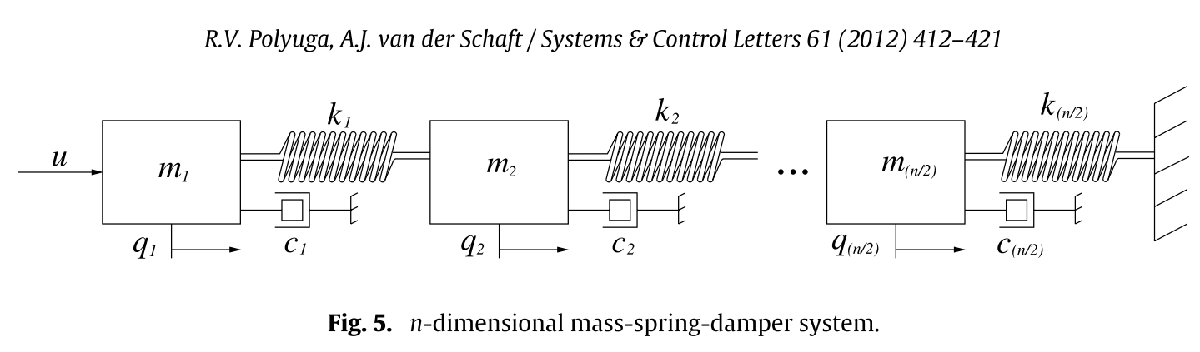

Image source: [3]

We consider a model with dimension $n = 100$, i.e. 50 masses ($m = 2$), 50 springs ($k = 1$), and 50 dampers ($d = 1$) .

sys = setup_MassSpringDamperSystem(100, 2, 1, 1, 'SISO')

sys =   phs with properties:

               J: [100×100 double]
               R: [100×100 double]
               Q: [100×100 double]
               G: [100×1 double]
               E: [100×100 double]
               P: [100×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 100
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


The most basic call to *cirkaPH* is by providing the system to reduce and the desired reduced order:

sysr = cirkaPH(sys, 20)

CIRKA step 002 - Convergence (combAny):  5.7e-02 4.9e-04 2.8e-04 


sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @cirkaPH
            info: [1×1 struct]
               J: [20×20 double]
               R: [20×20 double]
               Q: [20×20 double]
               G: [20×1 double]
               E: [20×20 double]
               P: [20×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 20
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


error = norm(sysr - sys)/norm(sys)

error = 4.1759e-04

### Initial shifts

By default, *cirkaPH* uses a vector of zeros for shift initialization. This is usually a cheap and still reasonably well working choice. If you want to change this, you can provide your own shifts as below:

shifts_log = ones(1, 20)

shifts_log =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


sysr_log = cirkaPH(sys, shifts_log)

CIRKA step 002 - Convergence (combAny):  7.2e-02 8.5e-04 8.3e-04 


sysr_log =   phsRed with properties:

      parameters: [1×1 struct]
          method: @cirkaPH
            info: [1×1 struct]
               J: [20×20 double]
               R: [20×20 double]
               Q: [20×20 double]
               G: [20×1 double]
               E: [20×20 double]
               P: [20×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 20
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


diff = norm(sysr_log - sysr)/norm(sysr)

diff = 1.2918e-06

### Options

Since *CIRKA-PH* is such a high-level algorithm, it provides many (nested) options. The levels of options are:

- Top level (*cirkaPH*): e.g. convergence criteria of CIRKA, initial shift strategies, maximum number of outer iterations

- Second level (*irkaPH, modelFctPH*): e.g. convergence criteria of IRKA, maximum number of inner itertions, update strategies

- Third level (*arnoldiPH*): e.g. structure preservation strategy

- Fourth level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help arnoldiPH

  arnoldiPH - reduces the system sys by the rational Arnoldi algorithm with
            interpolation points specified in s0.
 
  Syntax:
    redSys = arnoldiPH(sys, s0)
    redSys = arnoldiPH(sys, s0, Opts)
    redSys = arnoldiPH(sys, s0, b)
    redSys = arnoldiPH(sys, s0, b, Opts)
    [redSys,V,W,nLU] = arnoldiPH(sys, ...)
 
  Description:
        redSys = arnoldiPH(sys, s0) returns the reduced system redSys. It
        computes the ROM by interpolation of the transfer function with
        Krylov subspaces. The Arnoldi method has been adapted to PH systems
        (see References).
        The reduced system order will be as high as the number of
        interpolation points in s0 for real shifts. Imaginary shifts can be
        passed as complex conjugate values - if they are unique, the
        algorithm will complement the complex conjugate shifts.
 
        redS

To provide these options, use nested structs. As an example, the following code changes the execution parameters to run more inner iterations with decreased tolerance, follow a different structure preservation strategy, give more output, etc.:

Opts = struct();
Opts.maxIter = 10;          % Maximum number of outer iterations
Opts.stopCrit = 's0';       % Convergence criterion of CIRKA
Opts.irkaPH.maxIter = 50;   % Maximum number of inner (IRKA) iterations
Opts.irkaPH.tol = 1e-6;     % Tolerance for convergence criterion of IRKA
Opts.modelFctPH.phs.inputValidation = false;    % No PH structure validation for the surrogate model
Opts.irkaPH.arnoldiPH.structurePreservation = 'Cholesky';   % Structure preservation method
Opts.modelFctPH.structurePreservation = 'Cholesky';         % Structure preservation method for surrogate model (should coincide)
Opts.irkaPH.summary = true; % Show more information on irkaPH iterations
Opts

Opts = struct with fields:
       maxIter: 10
      stopCrit: 's0'
        irkaPH: [1×1 struct]
    modelFctPH: [1×1 struct]


sysr_custom = cirkaPH(sys, 20, Opts)

 IRKAPH stopped after 15 iterations
 Converged: yes
 Stopping criterion (s0): 7.112e-07
 IRKAPH stopped after 14 iterations
 Converged: yes
 Stopping criterion (s0): 8.869e-07
 IRKAPH stopped after 3 iterations
 Converged: yes
 Stopping criterion (s0): 5.458e-07
CIRKA step 003 - Convergence (s0):  6.6e-06 


sysr_custom =   phsRed with properties:

      parameters: [1×1 struct]
          method: @cirkaPH
            info: [1×1 struct]
               J: [20×20 double]
               R: [20×20 double]
               Q: [20×20 double]
               G: [20×1 double]
               E: [20×20 double]
               P: [20×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 20
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 1


## A closer look to the output

*cirkaPH* provides more outputs than only the reduced order system:

[sysr, V, W, s0, Rt, sysm, s0mTot, nLU] = cirkaPH(sys, 20)

CIRKA step 002 - Convergence (combAny):  5.7e-02 4.9e-04 2.8e-04 


sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @cirkaPH
            info: [1×1 struct]
               J: [20×20 double]
               R: [20×20 double]
               Q: [20×20 double]
               G: [20×1 double]
               E: [20×20 double]
               P: [20×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 20
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


V =     0.2635    0.7176    0.2092   -0.5024   -0.2581   -0.1372    0.1075    0.0907   -0.0443    0.0706    0.0644    0.0108   -0.0328    0.0318   -0.0190    0.0131   -0.0083   -0.0062    0.0050   -0.0062
   -0.8880    0.4196    0.1094    0.1221    0.0843    0.0041   -0.0191   -0.0267    0.0054   -0.0123   -0.0077   -0.0008    0.0033   -0.0030    0.0017   -0.0011    0.0007    0.0005   -0.0004    0.0005
    0.0880   -0.0813    0.5790    0.0594    0.4919   -0.3411    0.0488   -0.2678   -0.1242    0.0408    0.2289    0.0652   -0.1681    0.1849   -0.1281    0.1017   -0.0687   -0.0528    0.0441   -0.0582
    0.3611    0.5244   -0.0701    0.5430    0.3616    0.2076   -0.1826   -0.1176    0.0968   -0.1288   -0.1512   -0.0307    0.0860   -0.0875    0.0552   -0.0400    0.0260    0.0196   -0.0161    0.0205
   -0.0450   -0.0555   -0.0338   -0.4077    0.1817   -0.1891   -0.1853   -0.3265    0.2245   -0.3368   -0.3916   -0.1273    0.1997   -0.2304    0.1330   -0.0681    0.0418    0.0316   -0.0238  

W =     0.2638    0.7169    0.2139   -0.5040   -0.2579   -0.1370    0.1064    0.0870   -0.0437    0.0654    0.0604    0.0108   -0.0322    0.0308   -0.0191    0.0142   -0.0088   -0.0060    0.0034   -0.0147
   -0.8880    0.4197    0.1092    0.1222    0.0843    0.0041   -0.0191   -0.0265    0.0054   -0.0120   -0.0074   -0.0008    0.0033   -0.0029    0.0017   -0.0011    0.0007    0.0005   -0.0003    0.0011
    0.0910   -0.0930    0.6475    0.0214    0.5055   -0.3315    0.0321   -0.3328   -0.1225   -0.0471    0.1639    0.0690   -0.1584    0.1667   -0.1285    0.1144   -0.0732   -0.0493    0.0260   -0.1496
    0.3601    0.5272   -0.0885    0.5506    0.3597    0.2059   -0.1780   -0.1022    0.0950   -0.1072   -0.1349   -0.0310    0.0836   -0.0833    0.0556   -0.0440    0.0278    0.0188   -0.0105    0.0500
   -0.0505   -0.0771    0.0183   -0.5366    0.2794   -0.1752   -0.1698   -0.4594    0.1577   -0.4915   -0.5030   -0.0885    0.2226   -0.2872    0.1507   -0.0834    0.0659    0.0530   -0.0376  

s0 =    0.2535 - 1.3269i
   0.2535 + 1.3269i
   0.2462 - 1.1716i
   0.2462 + 1.1716i
   0.2575 - 0.9962i
   0.2575 + 0.9962i
   0.2469 - 0.8178i
   0.2469 + 0.8178i
   0.2385 - 0.6176i
   0.2385 + 0.6176i


Rt =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


sysm =   phsRed with properties:

      parameters: [1×1 struct]
          method: @modelFctPH
            info: [1×1 struct]
               J: [40×40 double]
               R: [40×40 double]
               Q: [40×40 double]
               G: [40×1 double]
               E: [40×40 double]
               P: [40×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 40
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


s0mTot =    0.2481 + 1.3206i   0.2481 - 1.3206i   0.2520 + 1.1523i   0.2520 - 1.1523i   0.2483 + 0.9484i   0.2483 - 0.9484i   0.2562 + 0.7777i   0.2562 - 0.7777i   0.2330 + 0.5849i   0.2330 - 0.5849i   0.2402 + 0.3867i   0.2402 - 0.3867i   0.2739 + 0.1846i   0.2739 - 0.1846i   0.2016 + 0.0000i   0.1618 + 0.0000i   0.0528 + 0.0000i   0.0269 + 0.0000i   0.0010 + 0.0000i   0.0088 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


nLU = 15

Here, $W$ and $V$ are the matrices which can be used to reduce the original system to the given reduced order system, *s0* (*Rt*) are the final shifts (tangent directions) which were used for reduction. *sysm* is the surrogate model, *s0mTot* are the shifts of the surrogate model. *nLU* is the number of high-dimensional LU-decompositions, i.e. the LU-decompositions required for computation of the surrogate model.

Additionally, even after the algorithm completed, the reduced order system gives some additional information which make its creation more transparent:

sysr.method         % Method with which the system was created (should be @cirkaPH)

ans = function_handle with value:
    @cirkaPH


sysr.parameters     % Execution parameters (Options, including defaults)

ans = struct with fields:
        initShifts: 'zeros'
       startShifts: [20×1 double]
      startTangent: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
               s0m: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
               Rtm: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
          stopCrit: 'combAny'
               tol: 1.0000e-03
            degTol: 5
           maxIter: 20
          modelTol: 1.0000e-03
         clearInit: 1
    stableModelFct: 1
            irkaPH: [1×1 struct]
        modelFctPH: [1×1 struct]
           verbose: 0
           summary: 1
              plot: 0
      suppressWarn: 0


sysr.info           % Additional information, e.g. on the iteration

ans = struct with fields:
                   s0: [20×1 double]
                   Rt: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
                  s0m: [0.2481 + 1.3206i 0.2481 - 1.3206i 0.2520 + 1.1523i 0.2520 - 1.1523i 0.2483 + 0.9484i 0.2483 - 0.9484i 0.2562 + 0.7777i 0.2562 - 0.7777i 0.2330 + 0.5849i 0.2330 - 0.5849i 0.2402 + 0.3867i 0.2402 - 0.3867i 0.2739 + 0.1846i … ]
                  Rtm: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
        finalStopCrit: [0.0568 4.8581e-04 2.7628e-04]
    stopCritEvolution: [2×3 double]
                kIrka: [10 8]
           nHighDimLU: 15
        originalOrder: 100
        modelFctOrder: 40
             relH2err: 4.1739e-04
               irkaPH: [1×1 struct]


Explanation of the info entries:

- *s0*:    Shifts for reduction of the original model

- *Rt*:    Tangent directions for reduction of the original model

- *s0m*:    Shifts for the surrogate model

- *Rtm*:    Tangent directions for the surrogate model

- *finalStopCrit*:    Final value(s) of the stopping criterium (criteria)

- *stopCritEvolution*:    Values of the stopping criterium/critieria for all iterations

- *kIrka*:    Number of inner IRKA iterations of each outer loop

- *nHighDimLU*:    Number of LU-decompositions required for computation of the final surrogate model

- *originalOrder*:    Order of the original system

- *modelFctOrder*:    Order of the final surrogate model

- *relH2err*:    Estimation of the relative H2 error (sysr vs sys) based on the surrogate model

- *irkaPH*:    Info entries of *irkaPH* (last outer iteration)

## Comparison: IRKA-PH - CIRKA-PH

To conclude this introduction, we will shortly compare *irkaPH* with *cirkaPH*. 

For this, we create two systems: one relatively small model with $n = 100$ and one large model with $n = 5000$.

sys_small = setup_MassSpringDamperSystem(100, 2, 1, 1);
sys_large = setup_MassSpringDamperSystem(5000, 2, 1, 1);

We reduce both systems with IRKA-PH and CIRKA-PH and compare their timings:

% Warm-up (required to avoid bad timing because of MATLAB internals)
irkaPH(sys_small, 20); cirkaPH(sys_small, 20);

 IRKAPH stopped after 10 iterations
 Converged: yes
 Stopping criterion (s0): 5.050e-04
CIRKA step 002 - Convergence (combAny):  5.7e-02 4.9e-04 2.8e-04 



% Comparison:
tic; sysr_small_irka = irkaPH(sys_small, 20); time_small_irka = toc

 IRKAPH stopped after 8 iterations
 Converged: yes
 Stopping criterion (s0): 5.921e-04


time_small_irka = 0.0678

tic; sysr_large_irka = irkaPH(sys_large, 20); time_large_irka = toc

 IRKAPH stopped after 47 iterations
 Converged: yes
 Stopping criterion (s0): 9.348e-04


time_large_irka = 6.4269

tic; sysr_small_cirka = cirkaPH(sys_small, 20); time_small_cirka = toc

CIRKA step 002 - Convergence (combAny):  5.7e-02 4.9e-04 2.8e-04 


time_small_cirka = 0.2344

tic; sysr_large_cirka = cirkaPH(sys_large, 20); time_large_cirka = toc

CIRKA step 005 - Convergence (combAny):  1.3e-01 1.5e-03 6.3e-04 


time_large_cirka = 2.6837

As you can see, for small systems, *cirkaPH* does not result in a better performance. However, if the original order is large, it can improve computation time significantly.

## References

[1] A. Castagnotto and B. Lohmann, "A new framework for H2-optimal model reduction," Mathematical and Computer Modelling of Dynamical Systems, vol. 24, no. 3, pp. 236–257, 2018.

[2] S. Gugercin, A. C. Antoulas, and C. A. Beattie. *H*2 Model Reduction for Large-Scale Linear Dynamical Systems. *SIAM J. Matrix Anal. Appl.*, 30(2):609-638, 2008.  

[3] R. V. Polyuga and A. van der Schaft. "Effort- and Flow-Constraint Reduction Methods for Structure Preserving Model Reduction of Port-Hamiltonian Systems." In: Systems Control Lett. 61(3), pp. 412–421, 2012.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Julius Durmann    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)